# F21 eksamen

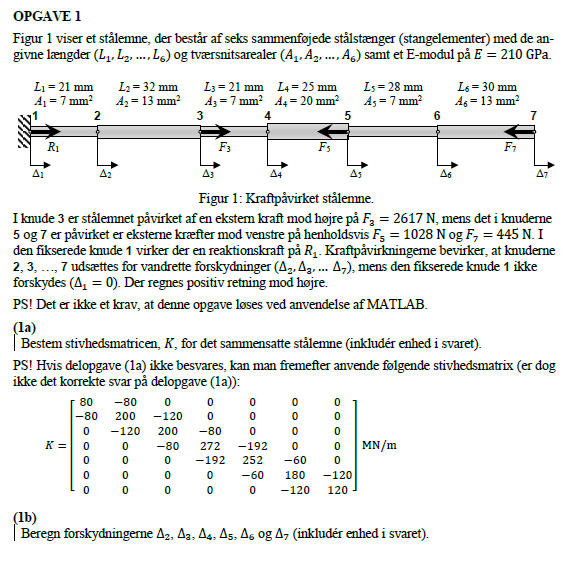

As = [7,13,7,20,7,13]; % mm2
Ls = [21,32,21,25,28,30]; % mm
E = 210; % GPa


n = length(As);

K = zeros(n+1, n+1);
for j = 1:n
    k= As(j)*E/Ls(j);

    Kelm = [k, -k; -k, k];

    K(j:j+1,j:j+1) = K(j:j+1,j:j+1) + Kelm;

end

K

K = 1.0e+02 *

   0.700000000000000  -0.700000000000000                   0                   0                   0                   0                   0
  -0.700000000000000   1.553125000000000  -0.853125000000000                   0                   0                   0                   0
                   0  -0.853125000000000   1.553125000000000  -0.700000000000000                   0                   0                   0
                   0                   0  -0.700000000000000   2.380000000000000  -1.680000000000000                   0                   0
                   0                   0                   0  -1.680000000000000   2.205000000000000  -0.525000000000000                   0
                   0                   0                   0                   0  -0.525000000000000   1.435000000000000  -0.910000000000000
                   0                   0                   0                   0                   0  -0.910000000000000   0.91000000000000

Stivhedsmatricen i MN/m

F3 = 2617;
F5 = -1028;
F7 = -445;

n_knuder = 7;

Pfri = [0 F3 0 F5 0 F7]';      % Eksterne kræfter på de frie knuder (N)
Kfri = K(2:n_knuder, 2:n_knuder);  % Del af stivhedsmatrix svarende til frie knuder (N/m). Knude 1 er fast indspændt
D = Kfri\Pfri;              % Forskydninger af de frie knuder (m)
D_my = D';

D_tot = [0 D_my]

D_tot =                    0  16.342857142857145  29.752380952380960   8.709523809523819  -0.058333333333323  -8.534523809523797 -13.424633699633686


Forskydninger bliver altså værdierne for knuderne 1-7, i mikrometer

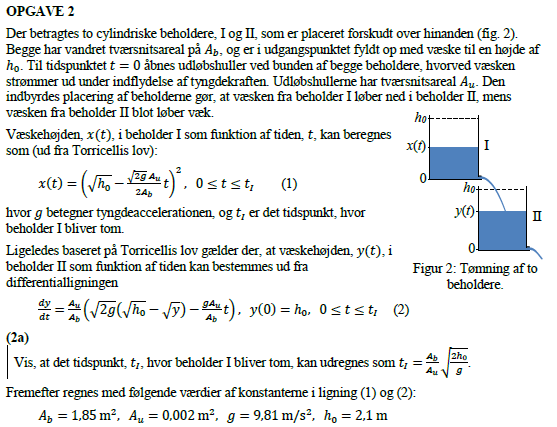

clear

% Der skal løses en ligning
syms h0 g Au Ab t
eq = sqrt(h0) - sqrt(2*g)*Au/(2*Ab)*t == 0;

s = solve(eq, t);

simplify(s)

$$ans = \frac{\sqrt{2}\,\mathrm{Ab}\,\sqrt{h_{0}}}{\mathrm{Au}\,\sqrt{g}}$$

Hvor det fremgår tydeligt at de 2 udtryk er ens

clear

Ab = 1.85; Au = 0.002; g = 9.81; h0 = 2.1;

dydt = @(t,y) Au/Ab * ((sqrt(2*g) * (sqrt(h0) - sqrt(y)) - g*Au/Ab * t))

dydt = function_handle with value:
    @(t,y)Au/Ab*((sqrt(2*g)*(sqrt(h0)-sqrt(y))-g*Au/Ab*t))



y0 = h0; h = 60;

t0 = 0;
t1 = Ab/Au * sqrt(2*h0/g);

span = [t0, t1];

[t,y,iter] = eulode(dydt,span,y0,h);


dy_dt = dydt(t,y);


disp(table(iter, t,y,dy_dt))

    iter           t                    y                    dy_dt        
    ____    ________________    _________________    _____________________

      0                    0                  2.1                        0
      1                   60                  2.1    -0.000687918188458729
      2                  120     2.05872490869248     -0.00130730237940015
      3                  180     1.98028676592847     -0.00186305966543863
      4                  240     1.86850318600215     -0.00235802354216347
      5                  300     1.72702177347234     -0.00279324762658287
      6                  360     1.55942691587737     -0.00316803100736666
      7                  420     1.36934505543537     -0.00347966177974971
      8                  480     1.16056534865039     -0.00372274477315428
      9                  540    0.9372

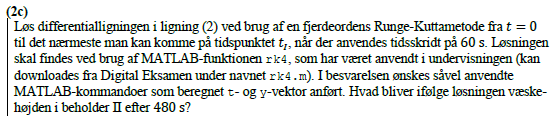

clear
format long
Ab = 1.85; Au = 0.002; g = 9.81; h0 = 2.1;

dydt = @(t,y) Au/Ab * ((sqrt(2*g) * (sqrt(h0) - sqrt(y)) - g*Au/Ab * t))

dydt = function_handle with value:
    @(t,y)Au/Ab*((sqrt(2*g)*(sqrt(h0)-sqrt(y))-g*Au/Ab*t))



y0 = h0; h = 120;

t0 = 0;
t1 = Ab/Au * sqrt(2*h0/g);

span = [t0, t1];

[t,Y, iter] = rk4system(dydt,span,y0,h);

disp(table(iter, t, Y, 'VariableNames',{'iter','Tid [s]', 'Væskehøjde [m]'}))

    iter    Tid [s]     Væskehøjde [m] 
    ____    _______    ________________

     0          0                   2.1
     1        120      2.02266936558235
     2        240      1.81024745668923
     3        360      1.49054207706892
     4        480      1.09176316365475
     5        600      0.64661538391934



Opgave d)

Man ville forvente den var mere præcis, eftersom der er flere skridt for metoden, og man ville forvente en lavere afvigelse med en faktor 2/3, eftersom det er ændringen i skridtet. TJEK MÅSKE VED IKKE OM JEG GIDER

# Opgave 3

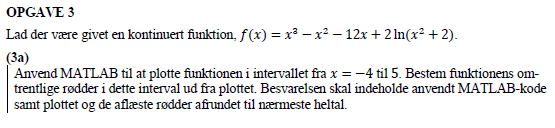

clear

f = @(x) x.^3 - x.^2 - 12*x + 2*log(x.^2 + 2);

fplot(f, [-4,5]), yline(0), xline(0), grid("minor")


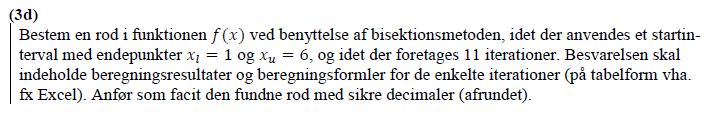

func = f;
xl = 1;
xu = 6;
maxit = 11;


[root,fx,ea,iter]=bisect(func,xl,xu, 0.01,maxit);

root =    3.780761718750000


fx =   -0.038876570896559


ea =    0.064574454345861


iter =     11


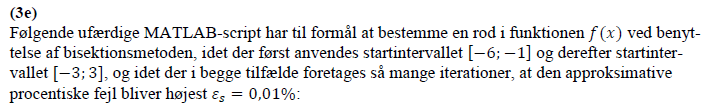

Den ufærdige kode:

clear, format long
f = @(x) x^3 - x^2 - 12*x + 2*log(x^2+2);
es = 0.01;
xl = -6; xu = -1;
while 1
  xr = (xl+xu)/2;
  Ea = (xu-xl)/2;
  ea = abs(Ea/xr*100);
  if (f(xl)<0 && f(xr) < 0) || (f(xl) > 0 && f(xr) > 0)
    xl = xr;
  elseif (f(xu)<0 && f(xr)<0) || (f(xu) > 0 && f(xr) > 0)
    xu = xr;
  end
  if ea <= es, break, end
end
xr, ea % Vis fundne rod og approks. procentisk fejl

xr =   -3.216491699218750


ea =    0.009487846069185


# Opgave 4

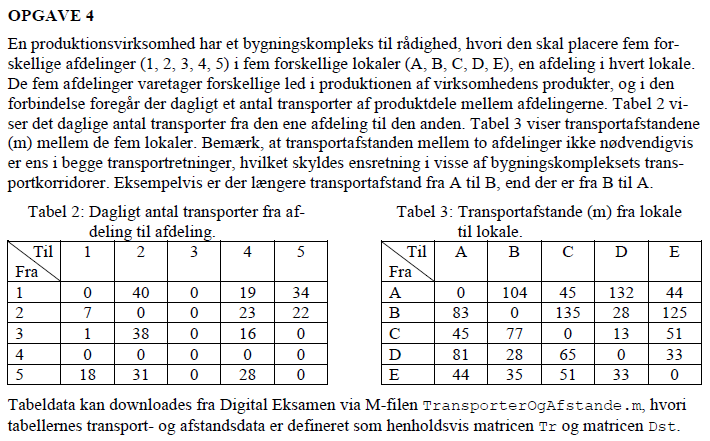

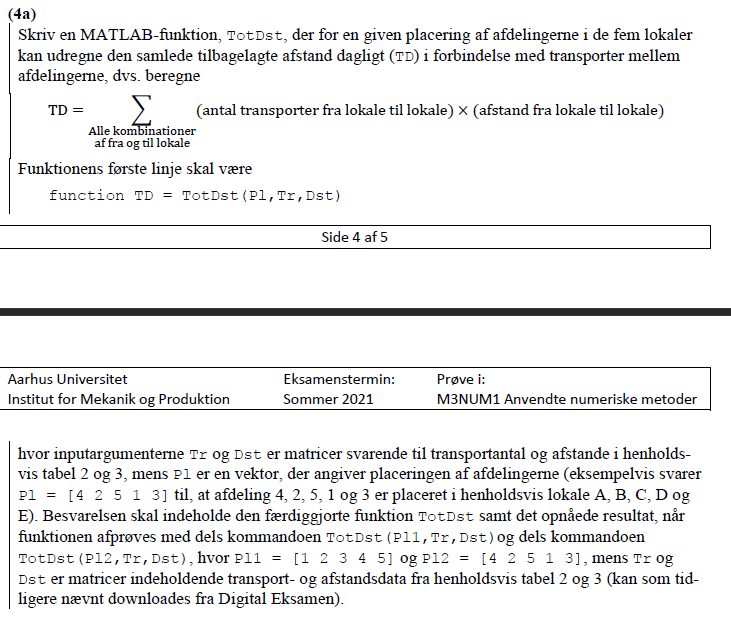

% Dagligt antal transporter fra afdeling til afdeling
Tr = [0    40     0    19    34
      7     0     0    23    22
      1    38     0    16     0
      0     0     0     0     0
     18    31     0    28     0];
   
% Transportafstande (m) fra lokale til lokale
Dst = [ 0   104    45   132    44
       83     0   135    28   125
       45    77     0    13    51
       81    28    65     0    33
       44    35    51    33     0];


Pl1 = [1 2 3 4 5]; % 1->A 2->B osv.

TD = [];
for i = 1:length(Pl1)
    
    for j = 1:length(Pl1)

        TD(end+1) = Tr(i, j) * Dst(Pl1(i), Pl1(j));

    end
end

TD = sum(TD)

TD = 18119

Scriptet laves til en funktion

Pl1 = [1 2 3 4 5];
Pl2 = [4 2 5 1 3],

Pl2 =      4     2     5     1     3



TD = TotDst(Pl1, Tr, Dst)

TD = 18119

TD2 = TotDst(Pl2, Tr, Dst)

TD2 = 15892

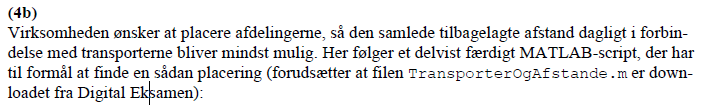

clear
TransporterOgAfstande;       % Opret matricer Tr og Dst
MuligePl = perms(1:length(Tr));  % Generér alle placeringsmuligheder
AntalPlIalt = numel(MuligePl(:,1));      % Antal placeringmuligheder i alt
MinTotDst = TotDst([1 2 3 4 5], Tr, Dst);

for i = 1:length(MuligePl)
  Pl = MuligePl(i,:);
  TD = TotDst(Pl,Tr,Dst);    % Kald af funktionen TotDst fra delopgave (a)
  if TD < MinTotDst
    PlMinTotDst = Pl;
    MinTotDst = TD;
  end
end
PlMinTotDst % Vis plac. svarende t. minimum samlet tilbagel. transportafst.

PlMinTotDst =      3     4     2     1     5


MinTotDst   % Vis minimum samlet tilbagelagt transportafstand

MinTotDst = 11853

# Funktioner

function [t,y,iter] = eulode(dydt,tspan,y0,h)
% eulode: Euler ODE solver
%   [t,y] = eulode(dydt,tspan,y0,h):
%           uses Euler's method to integrate an ODE
% input:
%   dydt = name of the M-file that evaluates the ODE
%   tspan = [ti, tf] where ti and tf = initial and
%   final values of independent variable
%   y0 = initial value of dependent variable
%   h = step size
% output:
%   t = vector of independent variable
%   y = vector of solution for dependent variable
if nargin<4,error('at least 4 input arguments required'),end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti),error('upper limit must be greater than lower'),end
t = (ti:h:tf)'; n = length(t);
% if necessary, add an additional value of t
% so that range goes from t = ti to tf
if t(n)<tf
    t(n+1) = tf;
    n = n+1;
end
y = y0*ones(n,1); %preallocate y to improve efficiency
iter = [0,];
for i = 1:n-1 %implement Euler's method
    iter(end+1) = i;
    y(i+1) = y(i) + dydt(t(i),y(i))*(t(i+1)-t(i));
end
iter = iter';
end



function [t,Y, iter] = rk4system(dYdt,tspan,Y0,h)
% rk4system: Fourth order Runge-Kutta solver for a system
%            of ODEs
%   [t,Y] = rk4system(dYdt,tspan,Y0,h): uses a fourth 
%     order Runge-Kutta method to solve a system of
%     first order differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;

iter = [0,];
for i = 1:n-1
    iter(end+1) = i;
  k1 = dYdt(t(i),Y(i,:));
  tmid1 = t(i) + h/2;
  Ymid1 = Y(i,:) + k1*h/2;
  k2 = dYdt(tmid1,Ymid1);
  tmid2 = t(i) + h/2;
  Ymid2 = Y(i,:) + k2*h/2;
  k3 = dYdt(tmid2,Ymid2);
  tend = t(i) + h;
  Yend = Y(i,:) + k3*h;
  k4 = dYdt(tend,Yend);
  phi = (k1 + 2*k2 + 2*k3 + k4)/6;
  Y(i+1,:) = Y(i,:) + phi*h;
end
iter = iter';
end


function [root,fx,ea,iter]=bisect(func,xl,xu,es,maxit)
% bisect: root location zeroes
%   [root,fx,ea,iter]=bisect(func,xl,xu,es,maxit):
%      uses bisection method to find the root of func
% input:
%   func = name of function
%   xl, xu = lower and upper guesses
%   es = desired relative error (default = 0.0001%)
%   maxit = maximum allowable iterations (default = 50)
% output:
%   root = real root
%   fx = function value at root
%   ea = approximate relative error (%)
%   iter = number of iterations
if nargin<3
    error('at least 3 input arguments required')
end

test = func(xl)*func(xu);

if test>0
    error('no sign change')
end

if nargin<4 || isempty(es)
    es= 0.0001;
end

if nargin<5||isempty(maxit)
    maxit= 50;
end

iter = 0; xr = xl; ea = 100;
while (1)
    xrold = xr;
    xr = (xl + xu)/2;
    iter = iter + 1;
    if xr ~= 0
        ea = abs((xr - xrold)/xr) * 100;
    end
    test = func(xl)*func(xr);
    if test < 0
        xu = xr;
    elseif test > 0
        xl = xr;
    else
        ea = 0;
    end
    if ea <= es || iter >= maxit
        break
    end
end

root = xr, fx = func(xr), ea = ea, iter = iter
end



function TD = TotDst(Pl, Tr, Dst)
TD = [];
for i = 1:length(Pl)
    
    for j = 1:length(Pl)

        TD(end+1) = Tr(i, j) * Dst(Pl(i), Pl(j));

    end
end

TD = sum(TD);
end













